# `Actividad 5.1 (Control de Posición)`

`A01798275 Bruno Manuel Zamora Garcia`

## 1. Introducción

En esta actividad se implementó un controlador en lazo cerrado para posicionar un robot diferencial en múltiples puntos deseados. El código de MATLAB desarrollado permite evaluar la respuesta en términos de trayectoria, error de posición y velocidades (lineal y angular) utilizando tres valores de ganancia (K = 5, 10 y 15).

Además, se plantea una estrategia para diseñar un controlador de ganancias auto-sintonizable que ajuste dinámicamente las ganancias de forma que se optimice el desempeño en tiempo real.

## 2. Pasos para Obtener el Control de Posición en las Coordenadas Deseadas

Los pasos seguidos para implementar el controlador son los siguientes:

Paso 1: Limpieza del Ambiente y Definición de Parámetros

- Limpieza: Se eliminan todas las variables, se cierran las figuras y se limpia la ventana de comandos para evitar interferencias.

- Parámetros de Simulación: Se define el tiempo total de simulación (`tf`), el intervalo de muestreo (`ts`) y se genera el vector de tiempo.Estos parámetros son esenciales para ejecutar la integración numérica (por ejemplo, con el método de Euler).

**Paso 2: Establecer las Condiciones Iniciales del Robot**

- Se fija la posición inicial del robot (en x y y) y la orientación inicial (`phi`).

- Estas condiciones son fundamentales para asegurar que todas las simulaciones parten del mismo estado.

**Paso 3: Definición de los Puntos Deseados**

- Se crea una lista o matriz (`desired_points`) en la cual cada fila representa las coordenadas deseadas [xd,yd].

- Esto permite realizar la simulación para cada uno de los 20 puntos de destino indicados.

**Paso 4: Configuración de los Valores de Ganancia**

- Se definen tres valores de ganancia ( 5, 10 y 15) que se usarán para evaluar la respuesta del sistema.

- La ganancia influye directamente en la rapidez de convergencia y en la estabilidad del sistema; valores muy bajos pueden dar respuestas lentas, mientras que valores muy altos pueden generar oscilaciones.

**Paso 5: Simulación del Control para Cada Punto Deseado**

- Bucle de Simulación: Por cada punto deseado, se simula el movimiento del robot usando cada valor de ganancia.

- Solo se simula en 2D por motivos de procesamiento, ya que la simulacion en 3D seria demasiado robusta

- Se computa el error entre el punto deseado y la posición actual del robot.

- Se aplica la ley de control utilizando la pseudoinversa de la matriz Jacobiana para calcular las velocidades lineal y angular.

- Mediante integración (método de Euler), se actualizan la posición y la orientación del robot.

- Los resultados (trayectorias, error, velocidades) se guardan en estructuras para su posterior análisis y graficación.

**Paso 6: Generación de Gráficas Comparativas**

- Se generan cuatro tipos de gráficos para cada punto deseado:

- Error de Posición vs Tiempo: Permite visualizar cómo decrece el error conforme el robot se aproxima al destino.

- Trayectorias: Se grafica el camino seguido por el robot, mostrando la posición inicial y el punto deseado.

- Velocidad Lineal vs Tiempo: Ayuda a observar la dinámica de la velocidad de avance.

- Velocidad Angular vs Tiempo: Muestra cómo se varía la rotación del robot para corregir la trayectoria.

- Cada gráfico incluye curvas correspondientes a los tres valores de ganancia, con lo que se puede comparar la eficacia de cada sintonización

## 3. Estrategia para el Diseño de un Controlador de Ganancias Auto-Sintonizable

Aunque en esta actividad se evaluaron tres valores de ganancia fijos (K = 5, 10, 15), en un entorno real o en aplicaciones avanzadas es deseable que el controlador ajuste automáticamente sus parámetros en función de la respuesta en tiempo real. En este punto planteare una estrategia para desarrollar un controlador auto-sintonizable:

**3.1. Observación y Medición del Error en Tiempo Real**

- Medición Continua: El controlador debe monitorear continuamente el error de posición, así como la derivada de este error (para evaluar la rapidez de cambio).

- Indicadores de Desempeño: Se pueden utilizar indicadores como el tiempo de asentamiento, el sobreimpulso y la variación en las velocidades (lineal y angular).

**3.2. Algoritmo de Adaptación de Ganancias**

- Control Adaptativo: Se puede emplear un esquema de control adaptativo en el cual, en función del error actual, se modifique la ganancia. Por ejemplo:

- Si el error es muy grande y la convergencia es muy lenta, se incrementa gradualmente la ganancia.

- Si se detectan oscilaciones o sobreimpulsos, se reduce la ganancia para evitar inestabilidad.

- Regla de Actualización: Una posible regla podría ser:

`if (error_actual > umbral_alto)`

`    K = K + delta;`

`elseif (error_actual < umbral_bajo)`

`    K = K - delta;`

`end`

Donde `umbral_alto` y `umbral_bajo` son valores determinados experimentalmente, y `delta` es el cambio en la ganancia.

**3.3. Integración con el Controlador Existente**

- Actualización en Tiempo Real: Modificar el bucle de simulación para que, en cada iteración, se evalúe el error y se ajuste la matriz de ganancia KKK de forma dinámica.

- Validación y Estabilidad: Es importante realizar pruebas de estabilidad para asegurarse de que la adaptación de la ganancia no cause inestabilidad en el sistema. Se puede usar un filtro o un algoritmo de actualización suave para evitar cambios bruscos.

**3.4. Ejemplo de Pseudocódigo para el Controlador Auto-Sintonizable**

Se puede plantear el siguiente pseudocódigo:

`Para cada instante de tiempo:`

`    Calcular el error de posición (he) = [hxd - hx; hyd - hy]`

`    Si el error > umbral_alto:`

`        Incrementar ganancia: K = K + delta`

`    Si el error < umbral_bajo:`

`        Disminuir ganancia: K = K - delta`

`    Calcular la matriz K con la ganancia actualizada`

`    Aplicar la ley de control: qpRef = pinv(J)*K*he`

`    Actualizar las velocidades y estados mediante integración`

`Fin para`

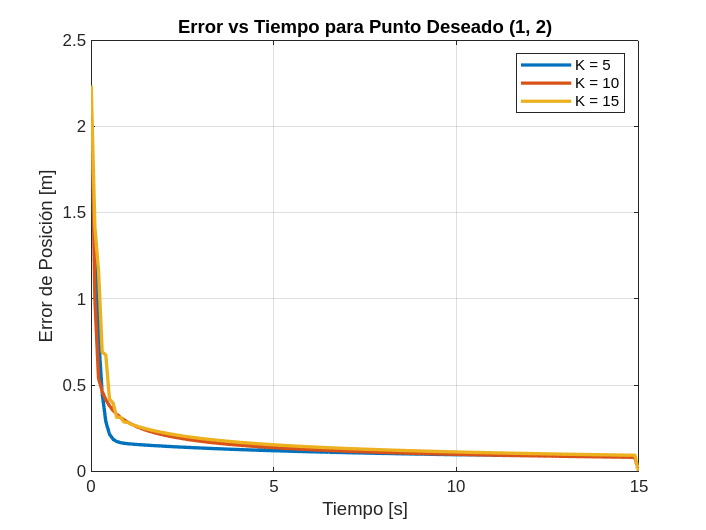

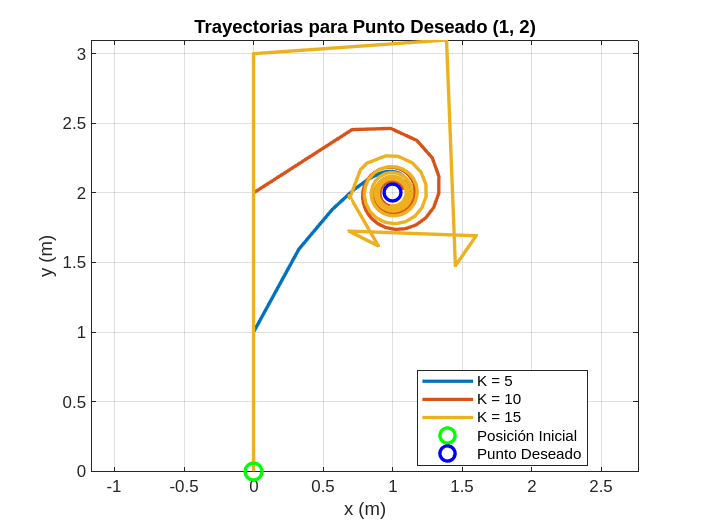

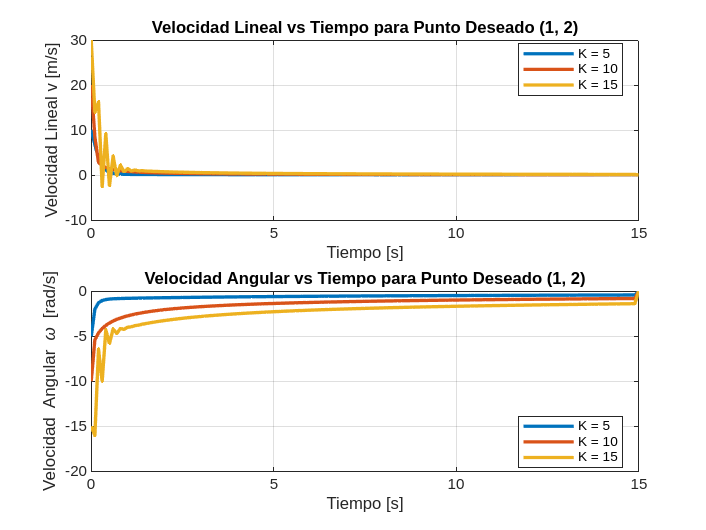

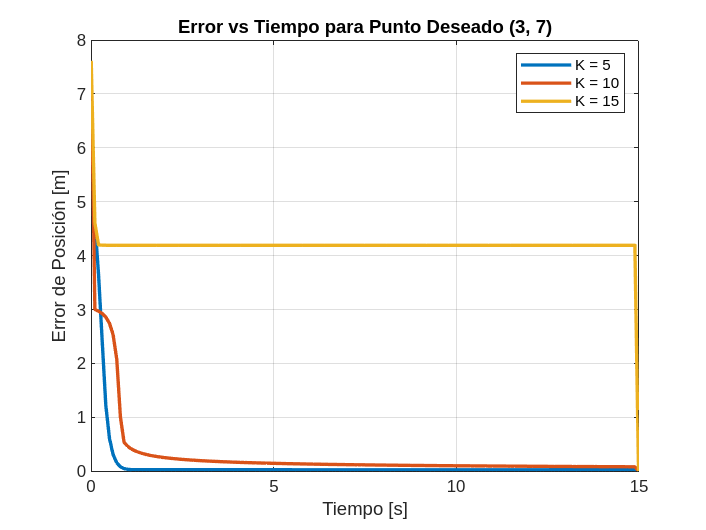

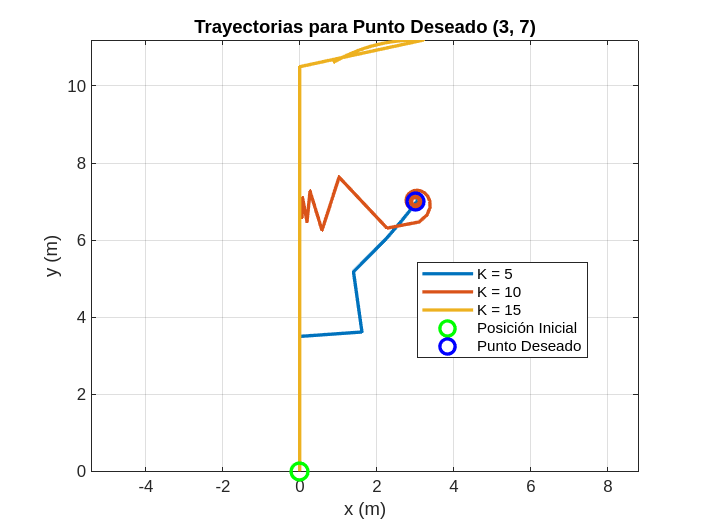

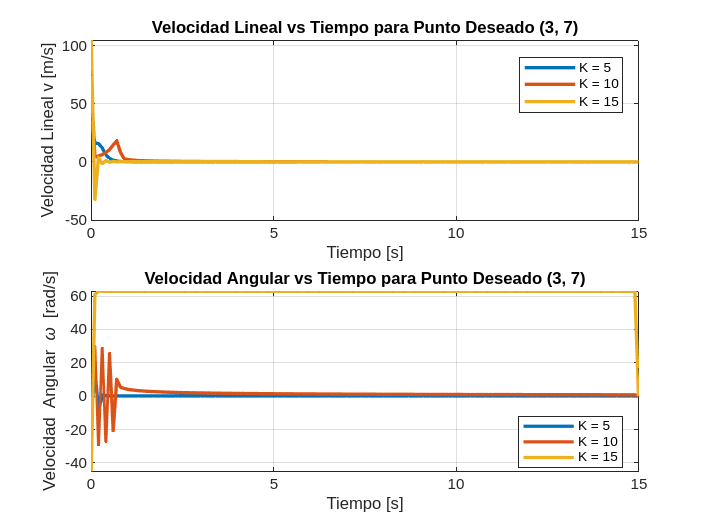

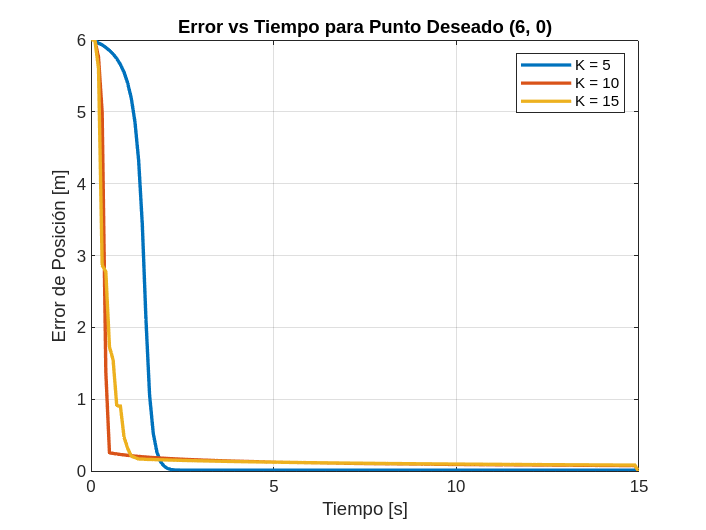

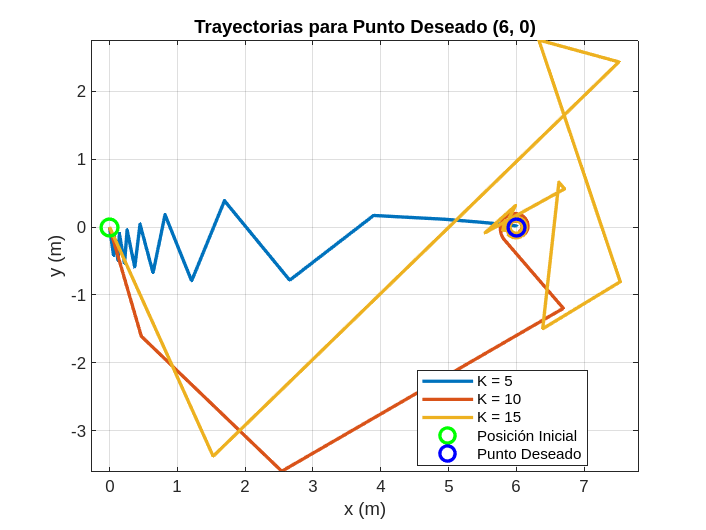

%% 0) LIMPIEZA DEL AMBIENTE
clear all;       % Borra todas las variables
close all;       % Cierra las figuras abiertas
clc;             % Limpia la ventana de comandos

%% 1) PARÁMETROS DE SIMULACIÓN
tf = 15;         % Tiempo total de simulación [s]
ts = 0.1;        % Tiempo de muestreo [s]
t = 0:ts:tf;     % Vector de tiempo
N = length(t);   % Número de muestras

%% 2) CONDICIONES INICIALES DEL ROBOT
init_x = 0;            % Posición inicial x [m]
init_y = 0;            % Posición inicial y [m]
init_phi = pi/2;       % Orientación inicial [rad] (90°)

%% 3) LISTA DE PUNTOS DESEADOS
% Cada fila corresponde a un punto: [x_d  y_d]
desired_points = [  1,    2;
                    3,    7;
                    6,    0;
                   -4,    5;
                   -6,    0;
                   -1,    0;
                   -7,   -7;
                   -2,   -4;
                   -0.5, -0.5;
                    1,   -3;
                    3,   -5;
                    8,    0;
                    0,   -3;
                    0,    9;
                    0,   -1;
                   -5,  -10;
                    7,   -7;
                    3,   -1;
                  -10,  -10;
                   10,    9];

%% 4) CONFIGURACIÓN DE LOS VALORES DE GANANCIA
gains = [5, 10, 15];

%% 5) SIMULACIÓN PARA CADA PUNTO DESEADO
for pt = 1:size(desired_points, 1)
    
    % Extraer coordenadas del punto deseado
    hxd = desired_points(pt, 1);
    hyd = desired_points(pt, 2);
    
    % Para almacenar la evolución del error para cada ganancia (para comparación)
    error_matrix = zeros(length(gains), N);
    
    % Guardar resultados de simulación para cada ganancia (estructura de datos)
    results = cell(length(gains), 1);
    
    % Bucle para cada valor de ganancia
    for g = 1:length(gains)
        % 5.a) Definir la ganancia actual y la matriz K
        Kval = gains(g);
        K = [Kval, 0; 0, Kval];
        
        % 5.b) Inicialización de las variables de estado
        x = zeros(1, N);      % Posición en x
        y = zeros(1, N);      % Posición en y
        phi = zeros(1, N);    % Orientación
        hx_vec = zeros(1, N); % Posición del punto de control en x
        hy_vec = zeros(1, N); % Posición del punto de control en y
        error_vec = zeros(1, N); % Error de posición
        v = zeros(1, N);      % Velocidad lineal
        w = zeros(1, N);      % Velocidad angular
        
        % Condiciones iniciales
        x(1) = init_x;
        y(1) = init_y;
        phi(1) = init_phi;
        hx_vec(1) = x(1);
        hy_vec(1) = y(1);
        
        % 5.c) Bucle de simulación (método de Euler)
        for k = 1:N-1
            % Calcular error: diferencia entre punto deseado y posición actual
            hxe = hxd - hx_vec(k);
            hye = hyd - hy_vec(k);
            he = [hxe; hye];
            error_vec(k) = sqrt(hxe^2 + hye^2);
            
            % Matriz Jacobiana (rotación en 2D)
            J = [cos(phi(k)), -sin(phi(k));
                 sin(phi(k)),  cos(phi(k))];
            
            % Ley de control (feedback utilizando la pseudoinversa)
            qpRef = pinv(J) * K * he;
            v(k) = qpRef(1);  % Velocidad lineal
            w(k) = qpRef(2);  % Velocidad angular
            
            % Actualización de orientación (integración con Euler)
            phi(k+1) = phi(k) + w(k)*ts;
            
            % Modelo cinemático para actualizar la posición
            xp = v(k)*cos(phi(k));
            yp = v(k)*sin(phi(k));
            x(k+1) = x(k) + xp*ts;
            y(k+1) = y(k) + yp*ts;
            
            % Actualizar la posición del punto de control
            hx_vec(k+1) = x(k+1);
            hy_vec(k+1) = y(k+1);
        end
        
        % Almacenar resultados para este valor de ganancia
        sim_result.x = x;
        sim_result.y = y;
        sim_result.hx = hx_vec;
        sim_result.hy = hy_vec;
        results{g} = sim_result;
        
        % Guardar la evolución del error para la comparación
        error_matrix(g,:) = error_vec;
    end % Fin de ganancia
    
    %% 6) GENERAR GRÁFICAS COMPARATIVAS PARA EL PUNTO DESEADO ACTUAL
    % Gráfica 1: Error de posición vs Tiempo para cada ganancia
    figure;
    hold on; grid on; box on;
    for g = 1:length(gains)
        plot(t, error_matrix(g,:), 'LineWidth', 2, ...
            'DisplayName', ['K = ' num2str(gains(g))]);
    end
    xlabel('Tiempo [s]');
    ylabel('Error de Posición [m]');
    title(['Error vs Tiempo para Punto Deseado (', num2str(hxd), ', ', num2str(hyd), ')']);
    legend('Location', 'northeast');
    
    % Gráfica 2: Trayectorias seguidas por el robot para cada ganancia
    figure;
    hold on; grid on; box on; axis equal;
    for g = 1:length(gains)
        sim_res = results{g};
        plot(sim_res.x, sim_res.y, 'LineWidth', 2, ...
            'DisplayName', ['K = ' num2str(gains(g))]);
    end
    plot(init_x, init_y, 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Posición Inicial');
    plot(hxd, hyd, 'bo', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Punto Deseado');
    xlabel('x (m)');
    ylabel('y (m)');
    title(['Trayectorias para Punto Deseado (', num2str(hxd), ', ', num2str(hyd), ')']);
    legend('Location', 'best');
    
    figure;
    % Subgráfica 1: Velocidad Lineal vs Tiempo
    subplot(2,1,1);
    hold on; grid on; box on;
    for g = 1:length(gains)
        sim_res = results{g};
        plot(t, sim_res.v, 'LineWidth', 2, ...
            'DisplayName', ['K = ' num2str(gains(g))]);
    end
    xlabel('Tiempo [s]');
    ylabel('Velocidad Lineal v [m/s]');
    title(['Velocidad Lineal vs Tiempo para Punto Deseado (', num2str(hxd), ', ', num2str(hyd), ')']);
    legend('Location', 'best');
    
    % Subgráfica 2: Velocidad Angular vs Tiempo
    subplot(2,1,2);
    hold on; grid on; box on;
    for g = 1:length(gains)
        sim_res = results{g};
        plot(t, sim_res.w, 'LineWidth', 2, ...
            'DisplayName', ['K = ' num2str(gains(g))]);
    end
    xlabel('Tiempo [s]');
    ylabel('Velocidad Angular \omega [rad/s]');
    title(['Velocidad Angular vs Tiempo para Punto Deseado (', num2str(hxd), ', ', num2str(hyd), ')']);
    legend('Location', 'best');
    
    pause(1);
end
